# Actividad 3: Problema del agente viajero (PAV)

**Optimización Matemática**

*Alejandra Nohemi Villarreal Barron*

*25 de agosto del 2025*

## **Introducción**

Esta actividad esta dirigida al estudio del comportamiento de los grafos para el problema del agente viajero. pero al igual em gustaria dar una breve introducción sobre el tema de teoria de grafos antes de comenzar con la programación.

### Definicion acuerdo a algunos autores.

*Graphs represent the concept of connection. In math, graphs are collections of nodes (also called vertices) and the connections, called edges, between them. *

*A node might be a city on a map or a person in a social network. An edge might be the route between two subway stations, or a follows relationship in social media.*

- Tate, B. (2022). *Programmer Passport: PROLOG*. Pragmatic Bookshelf.

*Graphs are simple data abstractions that lie behind networks of all stripes.*

*The graph provides the basic connection matrix, while the network maps the graph to a given subject domain and uses the wiring plan for its specific business goals.*

*Networks are found wherever distributed processes and systems occur and are used for all kinds of purposes.*

*...Yes, graphs are everywhere.*

- Hammond, T. (2023). Exploring graphs with elixir: Connect data with native graph libraries and graph databases. Pragmatic Programmers.

*El problema del viajante (o el problema del agente viajero), es un modelo de importancia superlativa en teoría de optimización. *

*Esta importancia, no se desprende de su aplicación directa, sino más bien por ser un problema marco para la rama de la optimización combinatoria.*

- Universidad Internacional de la Rioja, Optimización [Archivo PDF, tema 7].  Máster en Ingeniería Matemática y Computación. Documento proporcionado en el Campus Virtual.

## Objetivo

El objetivo de esta práctica, es implementar el Método de Held-Karp y comparar con el Metodo de Fuerza Bruta para hallar el recorrido óptimo del siguiente grafo.

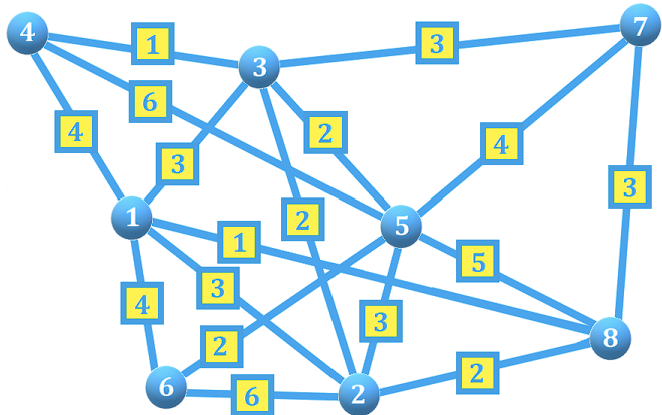

Suponga que cada vértice (nodo) representa un local donde un repartidor debe realizar una entrega. Si el repartidor dispone de 7 paquetes para entregar y sale de la tienda ubicada en el vertice 1, ¿cu,al debe ser el recorrido óptimo para regresar a la tienda en el menor tiempo posible? Además, determine la distancia que recorrió el repartidor.

## **Métodologia**

- Escribir la matriz de adyacencia con sus pesos y proporcione una gráfica del grafo con sus pesos, realizada en Matlab. 

- Determine el ciclo hamiltoniano óptimo, utilizando el Método de la Fuerza Bruta. En este caso, debe realizar una implementación en Matlab y adjuntarla a su trabajo. 

- Compruebe el resultado obtenido usando el Método de Held-Karp. NO necesita programar este método, utilice el fichero adjunto HeldKarp.m colgado en el Campus Virtual.

## Desarrollo

### Matriz de adjacencia y visualización

La matriz de adjacencia de un grafo es una forma organizada de describir sus conexiones.

En este caso, nuestro grafo tiene pesos o distancias que serian necesarias para descirbir sus conexiones en lugar de describirlas en boleanos 1 para si y 0 para no.

Nosotros utilizaremos 0 referirse al mismo nodo, inf cuando no existe conexion y el peso de cadaa conexion existente: 

**Ejemplo**: La fila correspondiente al nodo 1 seria **[0 3 3 4 inf 4 inf 1]**

0 porque se refiere a si mismo, 3 3 4 con sus conexiones con los nodos 2,3 y 4 el inf es debido a que no tiene conexion con el nodo 5 y asi para el resto.

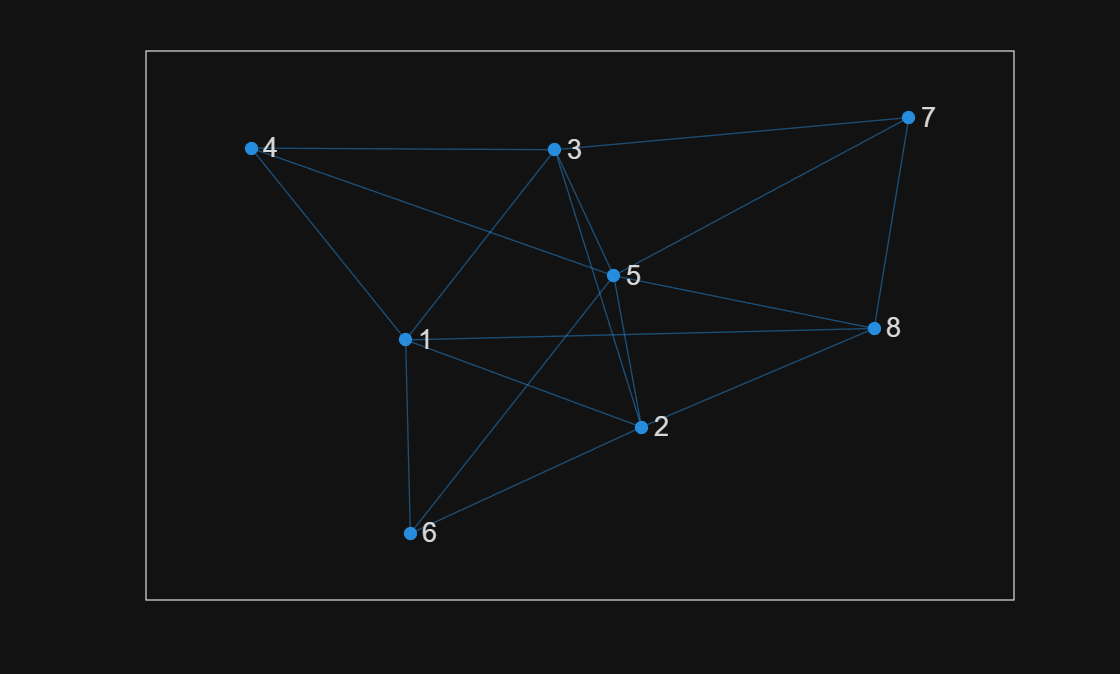

clear all   % Limpiamos
clc
% Para obtener una representacion grafica en matlab nuestra matriz de adjacencia quedaria de la siguiente manera
% colocamos 0s en los caminos que no existenten pero solo para la representacion grafica
adj = [0 3 3 4 0 4 0 1; 3 0 2 0 3 6 0 2; 3 2 0 1 2 0 3 0; 4 0 1 0 6 0 0 0; 
       0 3 2 6 0 2 4 5; 4 6 0 0 2 0 0 0; 0 0 3 0 4 0 0 3; 1 2 0 0 5 0 3 0]; 
figure
H = graph(adj);
h = plot(H);

### Método de fuerza bruta

Para nuestro analisis necesitariamos colocar inf en todas las conexiones no existentes para que al moemnto de analizarse se consideren con un coste muy alto y asi no sean tomadas como el camino con menor coste ya que si dejamos los 0s que utilizamos al crear la representacion grafica serian tomados como caminos sin costo o muy rapidos.

% Iniciamos contador tic-toc
tic

% Declaramos la matriz de adjacencia que en si es el conjunto de los caminos con los pesoso de cada uno
dmatrix = [
    0 3 3 4 inf 4 inf 1;            %conexiones de 1 al resto
    3 0 2 inf 3 6 inf 2;            %conexiones desde el nodo 2
    3 2 0 1 2 inf 3 inf;            %conexiones desde el nodo 3
    4 inf 1 0 6 inf inf inf;        %conexiones desde el nodo 4
    inf 3 2 6 0 2 4 5;              %conexiones desde el nodo 5
    4 6 inf inf 2 0 inf inf;        %conexiones desde el nodo 6
    inf inf 3 inf 4 inf 0 3;        %conexiones desde el nodo 7
    1 2 inf inf 5 inf 3 0];         %conexiones desde el nodo 8


fprintf('Nuestra matriz se veria de la sigueite forma:');

Nuestra matriz se veria de la sigueite forma:

dmatrix

dmatrix =      0     3     3     4   Inf     4   Inf     1
     3     0     2   Inf     3     6   Inf     2
     3     2     0     1     2   Inf     3   Inf
     4   Inf     1     0     6   Inf   Inf   Inf
   Inf     3     2     6     0     2     4     5
     4     6   Inf   Inf     2     0   Inf   Inf
   Inf   Inf     3   Inf     4   Inf     0     3
     1     2   Inf   Inf     5   Inf     3     0


%Declaramos la cantidad de vertices del grafo
A=1:length(dmatrix);

%Permutaciones posibles
Pos = perms(A);
Pos = Pos(end:-1:1,:);  % ordenamos las permutaciones

% Caminos posibles
Caminos = factorial(length(dmatrix)-1);
fprintf('Contamos con un total de %i permutaciones o caminos posibles', Caminos);

Contamos con un total de 5040 permutaciones o caminos posibles

%% Matriz de posibilidades
Posibilidades = zeros(Caminos,length(dmatrix)+1);       % inicializa en 0s
Posibilidades(:,1:end-1) = Pos(1:Caminos,:);            % Se llena con la sposibilidades
Posibilidades(:,end) = Pos(1:Caminos,1);                % fila extra con la posicion inicial para concluir el viaje

% Almacenamiento
[nRows,nCols] = size(Posibilidades);       
Coste = zeros(nRows,1);                      % Matriz para almacenar el coste

Min = 0; PosMin = 0;                        %inicializar variables temporales del minimo y su posicion

%% Bucle que recorre los caminos
for i = 1:nRows
    suma = 0;
    for j=1:length(A)            % Bucle para los vertices
    suma = suma + dmatrix(Posibilidades(i, j), Posibilidades(i, j+1));
    end
    Coste(i,1) = suma;         % Almacenamiento de costes
    if i == 1
        Min = Coste(1,1);          % Asigna el costo minimo a la primera fila
        PosMin = 1;
    end 
    if Min>Coste(i,1)              % va comparando el resto de costes
        Min = Coste(i,1);          % se actualizan las variables si el coste es menor
        PosMin = i;
    end
end

fprintf('El valor minimo %i se alcanza por el metodo de fuerza bruta con la siguiente secuencia', Coste(PosMin));

El valor minimo 22 se alcanza por el metodo de fuerza bruta con la siguiente secuencia

resultado = Posibilidades(PosMin,:)

resultado =      1     4     3     2     8     7     5     6     1


toc

Elapsed time is 0.194169 seconds.


### Método de Held Karp

Para el método de Held Karp llamamos a la funcion HeldKarp_gen.m que se adjuntara en el fichero final y fue proporcioada para esta actividad.

% probando el metodo de HeldKarp_gen 
type HeldKarp_gen.m


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%           ALGORITMO DE HELD-KARP PARA CAMINOS HAMILTONIANOS           %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Prof. Marlon Moscoso %%%%%%
clear all
clc
tic                                         % Inicio del contador de tiempo
%%                 Matriz de Adyacencia  - con pesos                     %%
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dmatrix = [
    inf 3 3 4 inf 4 inf 1;          %conexiones de 1 al resto
    3 inf 2 inf 3 6 inf 2;            %conexiones desde el nodo 2
    3 2 inf 1 2 inf 3 inf;            %conexiones desde el nodo 3
    4 inf 1 inf 6 inf inf inf;        %conexiones desde el nodo 4
    inf 3 2 6 inf 2 4 5;              %conexiones desde el nodo 5
    4 6 inf inf 2 inf inf inf;        %conexiones desde el nodo 6
    inf inf 3 inf 4 inf inf 3;        %conexiones desde el nodo 7
    1 2 inf inf 5 inf 3 inf];       %conexiones desde el n

HeldKarp_gen()

resultado =      1     4     3     2     8     7     5     6     1


optim = 22

Elapsed time is 0.191038 seconds.


## Conclusiones

A maea de conclusión en este ejercicio no tuvo mucha diferencia en la velocidad de la ejecución comparado con el método Held Karp, pero si no solo consideramos la velocidad si no tambien la siteraciones y la cantidad de nodos del grafo exto se va multiplicando y en caso de tener un grafo mas complejo o grande este tiempo y coste computacional se maximizaria.

Acordea lo analizado tenemos que:

En el método de **fuerza bruta** su dificultad es **O(n!)** es veloz en grafos pequeños e incluso podria funcionar mas rapido en algunos casos de grafos muy pequeños 

para el caso del método de **Held Karp**, su complejidad es alta **O(n² * 2ⁿ)**, es mejor que el de fuerza bruta pero su complejidad sigue teniendo un alto costo.

## Referencias

- Universidad Internacional de la Rioja, Optimización [Archivo PDF, tema 7].  Máster en Ingeniería Matemática y Computación. Documento proporcionado en el Campus Virtual.

- Tate, B. (2022). *Programmer Passport: PROLOG*. Pragmatic Bookshelf.

*- Hammond, T. (2023). Exploring graphs with elixir: Connect data with native graph libraries and graph databases. Pragmatic Programmers.*